# BME705: Rehabilitation Engineering

## Lab 3: Centre of Pressure & Sway Analysis

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BME705: Rehabilitation Engineering
% Lab 3: Center of Pressure (COP) and Sway Analysis
%
% Created by:  Devon Santillo and Dharmendra Gurve, 2020
% Updated by: Dan Genkin, 2021
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Name: Tanvir Hassan, Ilina Petrova
% Student ID: 501104056,

#### Loading Le Files

clear; clc; close all;
% Load the data and define the sampling frequency
fs = 2000;
load("ECEO_data4.mat");
load("sway_data3.mat");

### PART 1

% analyzeFP function: "Given" (do not edit): convert raw forceplate data
% INPUT = 16 channels of raw forceplate data;
% OUTPUT: xCOPL, yCOPL, xCOPR, yCOPR, Fz_R, Fz_L
% Note: Rv_R and Rv_L are vertical forces of right and left forceplate

% You can analyze the eyes open (EO) and eyes closed (EC) data seperately in a repeated process or in a logic loop
% but remember you cant have matrices as the iterative variable in a loop

#### **1.1 Calcualte and Plot the COPnet of the eyes open data**

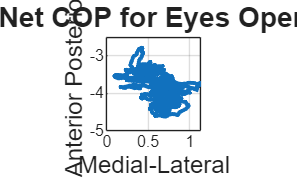

% Apply the provided function to obtain necessary outputs for further analysis
[xCOPL, yCOPL, xCOPR, yCOPR, Rv_R, Fz_L] = analyzeFP(qsEO_fp);

% Shift all X-coordinates to the middle of the split force plate by +/- 12.5825cm
xCOPL = xCOPL - 12.5825;
xCOPR = xCOPR + 12.5825;

% Filter all data
% Use of a Low-pass filter: a Butterworth is recommended
% define corner frequency and normalized cut-off frequency
fc=10;
Wn = fc / (fs / 2);
[b, a] = butter(4, Wn);
xCOPL = filtfilt(b, a, xCOPL);
yCOPL = filtfilt(b, a, yCOPL);
xCOPR = filtfilt(b, a, xCOPR);
yCOPR = filtfilt(b, a, yCOPR);
Rv_R = filtfilt(b, a, Rv_R);
Fz_L = filtfilt(b, a, Fz_L);

% Calculate COPnet for overall system using Equation A from the lab manual (Winter et al., 2003 [1]):
xCOP_net = (xCOPL .* (Fz_L ./ (Fz_L + Rv_R))) + (xCOPR .* (Rv_R ./ (Fz_L + Rv_R)));
yCOP_net = (yCOPL .* (Fz_L ./ (Fz_L + Rv_R))) + (yCOPR .* (Rv_R ./ (Fz_L + Rv_R)));

% Plot net COP (the stabilograms)
figure;
plot(xCOP_net, yCOP_net, 'LineWidth', 2);
title("Net COP for Eyes Open", 'FontSize', 14);
xlabel("Medial-Lateral", 'FontSize', 12);
ylabel("Anterior Posterior", 'FontSize', 12);
grid on;
axis equal;
axis square; % Make the plot square

#### 1.2 Calcualte and plot the COPnet of the eyes closed data

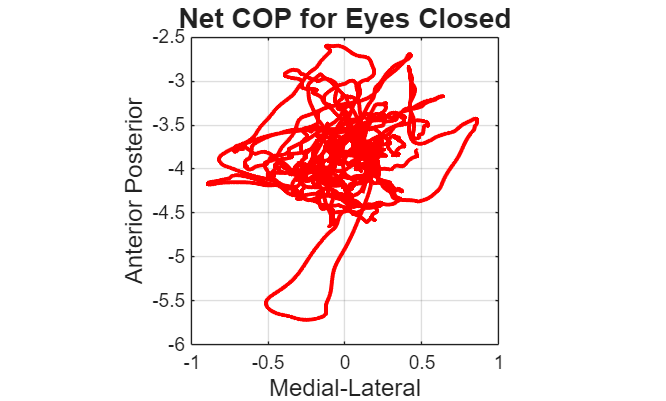

[xCOPL2, yCOPL2, xCOPR2, yCOPR2, Rv_R2, Fz_L2] = analyzeFP(qsEC_fp);
% Shift all X-coordinates to the middle of the split force plate by +/- 12.5825 cm
xCOPL2 = xCOPL2 - 12.5825;
xCOPR2 = xCOPR2 + 12.5825;

% Filter all data
% Use of a Low-pass filter: a Butterworth is recommended
% Define corner frequency and normalized cut-off frequency
fc = 10;
Wn = fc / (fs / 2);
[b, a] = butter(4, Wn);
xCOPL2 = filtfilt(b, a, xCOPL2);
yCOPL2 = filtfilt(b, a, yCOPL2);
xCOPR2 = filtfilt(b, a, xCOPR2);
yCOPR2 = filtfilt(b, a, yCOPR2);
Rv_R2 = filtfilt(b, a, Rv_R2);
Fz_L2 = filtfilt(b, a, Fz_L2);
% Calculate COPnet for overall system using Equation A from the lab manual (Winter et al., 2003 [1]):
xCOP_net2 = (xCOPL2 .* (Fz_L2 ./ (Fz_L2 + Rv_R2))) + (xCOPR2 .* (Rv_R2 ./ (Fz_L2 + Rv_R2)));
yCOP_net2 = (yCOPL2 .* (Fz_L2 ./ (Fz_L2 + Rv_R2))) + (yCOPR2 .* (Rv_R2 ./ (Fz_L2 + Rv_R2)));
% Plot net COP (the stabilograms)
figure;
plot(xCOP_net2, yCOP_net2, 'LineWidth', 2, 'Color', 'r');
title("Net COP for Eyes Closed", 'FontSize', 14);
xlabel("Medial-Lateral", 'FontSize', 12);
ylabel("Anterior Posterior", 'FontSize', 12);
grid on;
axis equal;
axis square; % Make the plot square

#### 1.3 Find total excursions and mean velocity using equations B-I

% Using the method described in Prieto el al., 1994 paper [2]
% Select 20 seconds of the data in the time frame from 40-60 seconds
T=20;
start_point = fs*40;
end_point = fs*60;
xCOP_segment = xCOP_net(start_point:end_point);
yCOP_segment = yCOP_net(start_point:end_point);

% Downsample A/P and M/L axes to 100 Hz
fs_new = 100;
xCOP_downsampled = downsample(xCOP_segment, fs / fs_new);
yCOP_downsampled = downsample(yCOP_segment, fs / fs_new);

% Zero-mean AP and ML : Equations B & C (Prieto el al., 1994)
xCOP_zero_mean = xCOP_downsampled - mean(xCOP_downsampled); %AP
yCOP_zero_mean = yCOP_downsampled - mean(yCOP_downsampled); %ML

% Total Excursion: Equations D-F (Prieto el al., 1994)
% Calculate TOTEX ML, AP, Net for Open and Closed
TOTEXap = 0;
TOTEXml = 0;
TOTEX = 0;
for i = 1:length(xCOP_zero_mean) - 1
   TOTEXap = TOTEXap + abs(xCOP_zero_mean(i+1) - xCOP_zero_mean(i));
   TOTEXml = TOTEXml + abs(yCOP_zero_mean(i+1) - yCOP_zero_mean(i));
   TOTEX = TOTEX + sqrt((xCOP_zero_mean(i+1) - xCOP_zero_mean(i))^2 + (yCOP_zero_mean(i+1) - yCOP_zero_mean(i))^2);
end

% Mean velocity: Equations G-I (Prieto el al., 1994)
mean_velocity_ap = TOTEXap / T;
mean_velocity_ml = TOTEXml / T;
mean_velocity_net = TOTEX / T;


For Eyes Closed


xCOP_segment2 = xCOP_net2(start_point:end_point);
yCOP_segment2 = yCOP_net2(start_point:end_point);

% Downsample A/P and M/L axes to 100 Hz
xCOP_downsampled2 = downsample(xCOP_segment2, fs / fs_new);
yCOP_downsampled2 = downsample(yCOP_segment2, fs / fs_new);

% Zero-mean AP and ML : Equations B & C (Prieto el al., 1994)
xCOP_zero_mean2 = xCOP_downsampled2 - mean(xCOP_downsampled2); % AP
yCOP_zero_mean2 = yCOP_downsampled2 - mean(yCOP_downsampled2); % ML

% Total Excursion: Equations D-F (Prieto et al., 1994)
% Calculate TOTEX ML, AP, Net for Eyes Closed
TOTEXap2 = 0;
TOTEXml2 = 0;
TOTEX2 = 0;
for i = 1:length(xCOP_zero_mean2) - 1
   TOTEXap2 = TOTEXap2 + abs(xCOP_zero_mean2(i+1) - xCOP_zero_mean2(i));
   TOTEXml2 = TOTEXml2 + abs(yCOP_zero_mean2(i+1) - yCOP_zero_mean2(i));
   TOTEX2 = TOTEX2 + sqrt((xCOP_zero_mean2(i+1) - xCOP_zero_mean2(i))^2 + (yCOP_zero_mean2(i+1) - yCOP_zero_mean2(i))^2);
end

% Mean velocity: Equations G-I (Prieto el al., 1994)
mean_velocity_ap2 = TOTEXap2 / T;
mean_velocity_ml2 = TOTEXml2 / T;
mean_velocity_net2 = TOTEX2 / T;
% Display results in a formatted table for lab report
Metrics = {'Total Excursion (AP) (cm)'; 'Total Excursion (ML) (cm)'; 'Total Excursion (Net) (cm)'; ...
          'Mean Velocity (AP) (cm/s)'; 'Mean Velocity (ML) (cm/s)'; 'Mean Velocity (Net) (cm/s)'};
EyesOpen = [TOTEXap; TOTEXml; TOTEX; mean_velocity_ap; mean_velocity_ml; mean_velocity_net];
EyesClosed = [TOTEXap2; TOTEXml2; TOTEX2; mean_velocity_ap2; mean_velocity_ml2; mean_velocity_net2];
resultsTable = table(Metrics, EyesOpen, EyesClosed);

% Format the table for better readability in lab report
disp('Results Summary:');

Results Summary:


disp(resultsTable);

               Metrics                EyesOpen    EyesClosed
    ______________________________    ________    __________

    {'Total Excursion (AP) (cm)' }     38.988       19.739  
    {'Total Excursion (ML) (cm)' }     334.25       127.59  
    {'Total Excursion (Net) (cm)'}     343.76       131.43  
    {'Mean Velocity (AP) (cm/s)' }     1.9494      0.98694  
    {'Mean Velocity (ML) (cm/s)' }     16.713       6.3793  
    {'Mean Velocity (Net) (cm/s)'}     17.188       6.5716  



% fprintf('\n');
% fprintf('--------------------------------------------------\n');
% fprintf('%-30s %-20s %-20s\n', 'Metrics', 'Eyes Open', 'Eyes Closed');
% fprintf('--------------------------------------------------\n');
% for i = 1:length(Metrics)
%     fprintf('%-30s %-20.2f %-20.2f\n', Metrics{i}, EyesOpen(i), EyesClosed(i));
% end
% fprintf('--------------------------------------------------\n');

### PART 2

#### 2.1 Processing EMG data: Consider the timing of activation of the Sol. and TA muscles with respect to the COP sway in the AP direction.

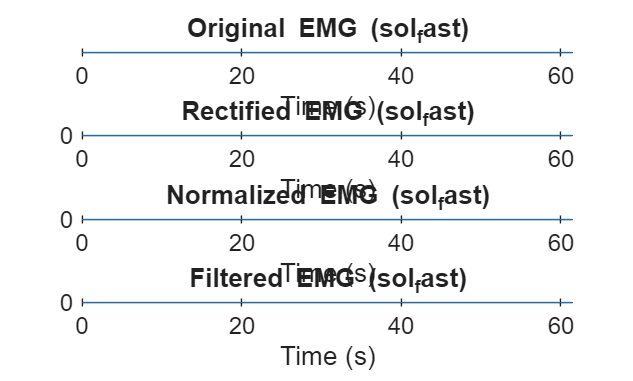

G = 1000; %gain
fs = 2000; % sampling rate 200Hz

% Define time vectors
t_fast = (0:length(fp_fast)-1) / fs;
t_slow = (0:length(fp_slow)-1) / fs;

% Process sol_fast
sol_fast = sol_fast / G; % Normalize gain
sol_fast = sol_fast * 1000; % Convert to mV
sol_fast_rectified = abs(sol_fast);
sol_fast_rectified_max = max(sol_fast_rectified);
sol_fast_normalized = sol_fast_rectified / sol_fast_rectified_max;
sol_fast_filtered = filtfilt(b, a, sol_fast_normalized); % Apply zero-phase filtering

% Process sol_slow
sol_slow = sol_slow / G; % Normalize gain
sol_slow = sol_slow * 1000; % Convert to mV
sol_slow_rectified = abs(sol_slow);
sol_slow_rectified_max = max(sol_slow_rectified);
sol_slow_normalized = sol_slow_rectified / sol_slow_rectified_max;
sol_slow_filtered = filtfilt(b, a, sol_slow_normalized); % Apply zero-phase filtering

% Process ta_fast
ta_fast = ta_fast / G; % Normalize gain
ta_fast = ta_fast * 1000; % Convert to mV
ta_fast_rectified = abs(ta_fast);
ta_fast_rectified_max = max(ta_fast_rectified);
ta_fast_normalized = ta_fast_rectified / ta_fast_rectified_max;
ta_fast_filtered = filtfilt(b, a, ta_fast_normalized); % Apply zero-phase filtering

% Process ta_slow
ta_slow = ta_slow / G; % Normalize gain
ta_slow = ta_slow * 1000; % Convert to mV
ta_slow_rectified = abs(ta_slow);
ta_slow_rectified_max = max(ta_slow_rectified);
ta_slow_normalized = ta_slow_rectified / ta_slow_rectified_max;
ta_slow_filtered = filtfilt(b, a, ta_slow_normalized); % Apply zero-phase filtering

function processEMG(EMGdata, t_EMG, EMG_rectified, EMG_rectified_max, EMG_normalized, EMG_filtered)
    fs = 2000; % sampling rate 200Hz
    % Original EMG plot
    figure;
    subplot(4, 1, 1);
    plot(t_EMG, EMGdata, 'LineWidth', 1.5);
    title(['Original EMG (' inputname(1) ')'], 'FontSize', 14);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('EMG (mV)', 'FontSize', 12);
    grid on;
    set(gca, 'FontSize', 12);

    % Rectification
    EMG_rectified = abs(EMGdata);
    subplot(4, 1, 2);
    plot(t_EMG, EMG_rectified, 'LineWidth', 1.5);
    title(['Rectified EMG (' inputname(1) ')'], 'FontSize', 14);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Rectified EMG (mV)', 'FontSize', 12);
    grid on;
    set(gca, 'FontSize', 12);

    % Normalization
    EMG_rectified_max = max(EMG_rectified);
    EMG_normalized = EMG_rectified / EMG_rectified_max;
    subplot(4, 1, 3);
    plot(t_EMG, EMG_normalized, 'LineWidth', 1.5);
    title(['Normalized EMG (' inputname(1) ')'], 'FontSize', 14);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Normalized EMG (mV)', 'FontSize', 12);
    grid on;
    set(gca, 'FontSize', 12);

    % Signal Envelope Filtering (2.5 Hz low-pass filter)
    fc = 2.5; % cutoff frequency
    [b, a] = butter(4, fc/(fs/2));
    EMG_filtered = filtfilt(b, a, EMG_normalized); % Use filtfilt for zero-phase distortion
    subplot(4, 1, 4);
    plot(t_EMG, EMG_filtered, 'LineWidth', 1.5);
    title(['Filtered EMG (' inputname(1) ')'], 'FontSize', 14);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Filtered EMG (mV)', 'FontSize', 12);
    grid on;
    set(gca, 'FontSize', 12);
end

% Call the function with sol_fast and t_fast
processEMG(sol_fast, t_fast, sol_fast_rectified, sol_fast_rectified_max, sol_fast_normalized, sol_fast_filtered);

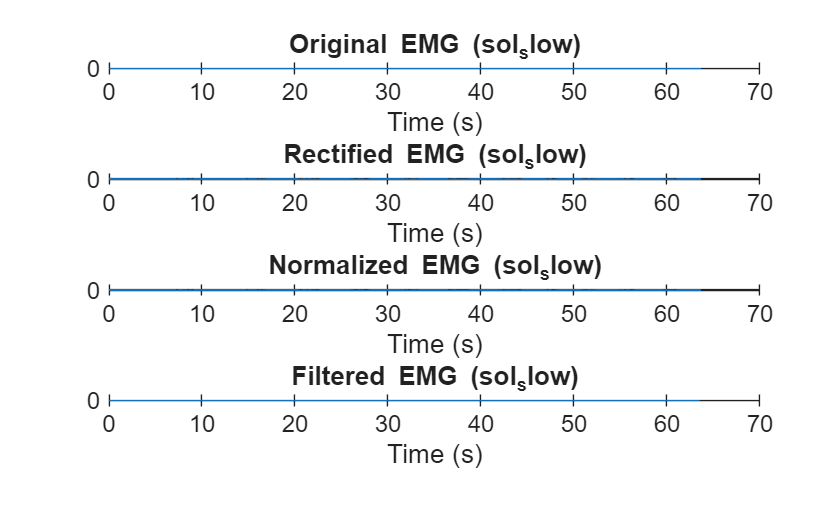

processEMG(sol_slow, t_slow, sol_slow_rectified, sol_slow_rectified_max, sol_slow_normalized, sol_slow_filtered);

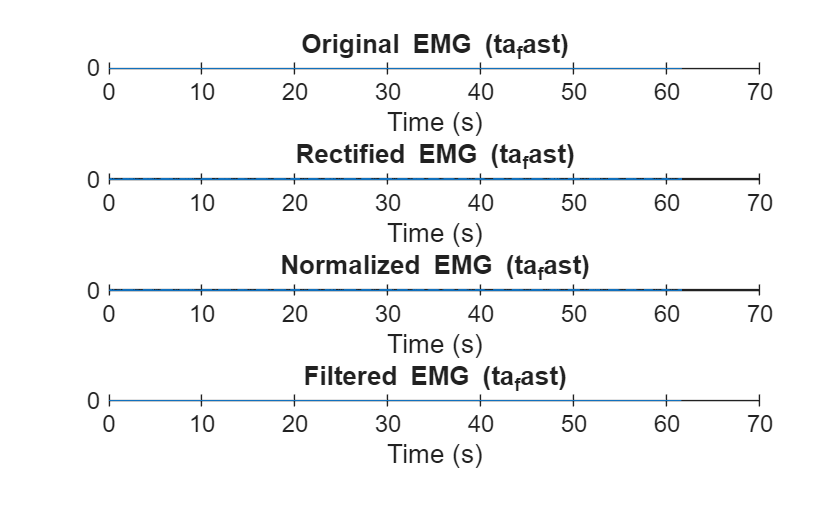

processEMG(ta_fast, t_fast, ta_fast_rectified, ta_fast_rectified_max, ta_fast_normalized, ta_fast_filtered);

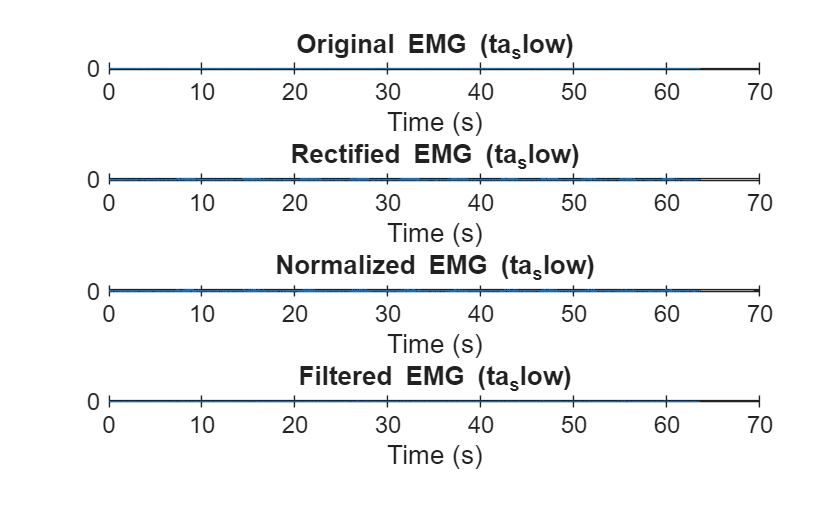

processEMG(ta_slow, t_slow, ta_slow_rectified, ta_slow_rectified_max, ta_slow_normalized, ta_slow_filtered);

#### 2.2 Processing sway data (ML, AP) - Repeat force plate analysis

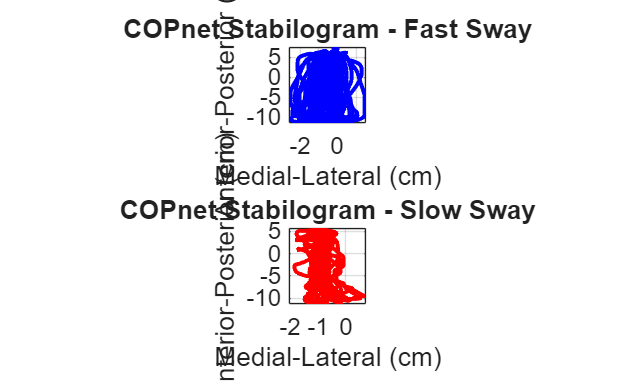

% This section should follow the first part of the analysis
% call the analyzeFP function again (do not edit it)
[xCOPL, yCOPL, xCOPR, yCOPR, Rv_R, Fz_L] = analyzeFP(fp_fast);
[xCOPL2, yCOPL2, xCOPR2, yCOPR2, Rv_R2, Fz_L2] = analyzeFP(fp_slow);
% Apply the provided function to obtain necessary outputs for further analysis

% Shift X-coordinates to the middle of the split force plate by +/- 12.5825cm
xCOPL = xCOPL - 12.5825;
xCOPR = xCOPR + 12.5825;
xCOPL2 = xCOPL2 - 12.5825;
xCOPR2 = xCOPR2 + 12.5825;

% Filter all the slow & fast, L & R COP data
fc = 10;
Wn = fc / (fs / 2);
[b, a] = butter(4, Wn);

% Apply filtering to fast sway data
xCOPL = filtfilt(b, a, xCOPL);
yCOPL = filtfilt(b, a, yCOPL);
xCOPR = filtfilt(b, a, xCOPR);
yCOPR = filtfilt(b, a, yCOPR);
Rv_R = filtfilt(b, a, Rv_R);
Fz_L = filtfilt(b, a, Fz_L);

% Apply filtering to slow sway data
xCOPL2 = filtfilt(b, a, xCOPL2);
yCOPL2 = filtfilt(b, a, yCOPL2);
xCOPR2 = filtfilt(b, a, xCOPR2);
yCOPR2 = filtfilt(b, a, yCOPR2);
Rv_R2 = filtfilt(b, a, Rv_R2);
Fz_L2 = filtfilt(b, a, Fz_L2);

% Calculate COPnet for overall system of both fast and slow sway using Equation A from the lab manual
% Fast sway
xCOP_net = (xCOPL .* (Fz_L ./ (Fz_L + Rv_R))) + (xCOPR .* (Rv_R ./ (Fz_L + Rv_R)));
yCOP_net = (yCOPL .* (Fz_L ./ (Fz_L + Rv_R))) + (yCOPR .* (Rv_R ./ (Fz_L + Rv_R)));
% Slow sway
xCOP_net2 = (xCOPL2 .* (Fz_L2 ./ (Fz_L2 + Rv_R2))) + (xCOPR2 .* (Rv_R2 ./ (Fz_L2 + Rv_R2)));
yCOP_net2 = (yCOPL2 .* (Fz_L2 ./ (Fz_L2 + Rv_R2))) + (yCOPR2 .* (Rv_R2 ./ (Fz_L2 + Rv_R2)));

% Plot Fast and slow COPnet Stabilograms with improved visualization
figure;

% Fast sway
subplot(2,1,1);
plot(xCOP_net, yCOP_net, 'LineWidth', 2, 'Color', 'b'); % Increased line width and changed color
title('COPnet Stabilogram - Fast Sway', 'FontSize', 14);
xlabel('Medial-Lateral (cm)', 'FontSize', 12);
ylabel('Anterior-Posterior (cm)', 'FontSize', 12);
grid on;
axis equal;
axis square; % Make the plot square
set(gca, 'FontSize', 12);

% Slow sway
subplot(2,1,2);
plot(xCOP_net2, yCOP_net2, 'LineWidth', 2, 'Color', 'r'); % Increased line width and changed color
title('COPnet Stabilogram - Slow Sway', 'FontSize', 14);
xlabel('Medial-Lateral (cm)', 'FontSize', 12);
ylabel('Anterior-Posterior (cm)', 'FontSize', 12);
grid on;
axis equal;
axis square; % Make the plot square
set(gca, 'FontSize', 12);

#### 2.3 Plot the slow and fast EMG and the Sway data together

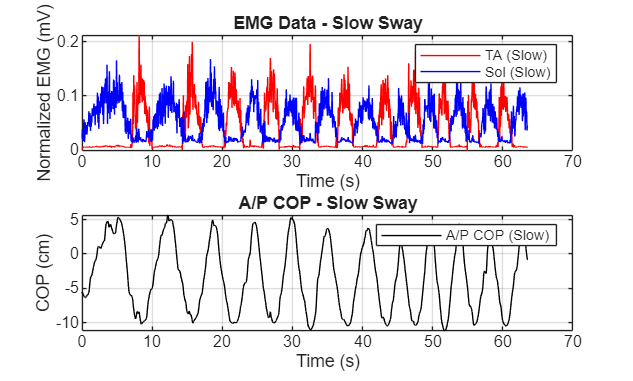

% slow
figure;
% Subplot 1: EMG data for slow sway (TA and Sol)
subplot(2,1,1);
plot(t_slow, ta_slow_filtered, 'r', 'DisplayName', 'TA (Slow)');
hold on;
plot(t_slow, sol_slow_filtered, 'b', 'DisplayName', 'Sol (Slow)');
title('EMG Data - Slow Sway');
xlabel('Time (s)');
ylabel('Normalized EMG (mV)');
legend('show');
grid;
hold off;
% Subplot 2: A/P COP for slow sway
subplot(2,1,2);
plot(t_slow, yCOP_net2, 'k', 'DisplayName', 'A/P COP (Slow)');
title('A/P COP - Slow Sway');
xlabel('Time (s)');
ylabel('COP (cm)');
grid;
legend('show');

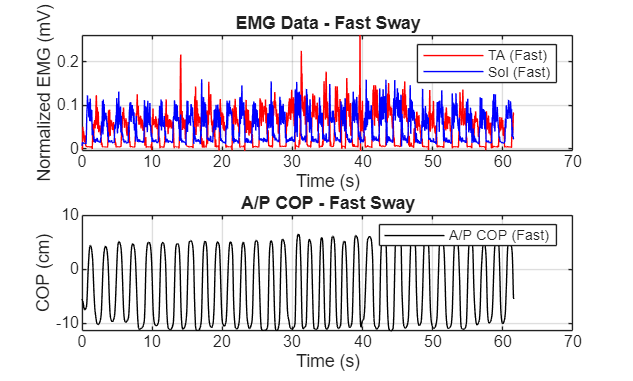

% fast
figure;
% Subplot 1: EMG data for fast sway (TA and Sol)
subplot(2,1,1);
plot(t_fast, ta_fast_filtered, 'r', 'DisplayName', 'TA (Fast)');
hold on;
plot(t_fast, sol_fast_filtered, 'b', 'DisplayName', 'Sol (Fast)');
title('EMG Data - Fast Sway');
xlabel('Time (s)');
ylabel('Normalized EMG (mV)');
legend('show');
grid;
hold off;
% Subplot 2: A/P COP for fast sway
subplot(2,1,2);
plot(t_fast, yCOP_net, 'k', 'DisplayName', 'A/P COP (Fast)');
title('A/P COP - Fast Sway');
xlabel('Time (s)');
ylabel('COP (cm)');
grid;
legend('show');